# Quitar distorsión de imágenes segmentadas

% =========================================================================
% SCRIPT COMPLETO: 
%   Paso 1) Quitar distorsión y recortar todas las imágenes segmentadas
%   Paso 2) Reconstruir las imágenes 360° corregidas al dominio 
%           polar (r,θ) para generar el panorama (unwrap)
% =========================================================================

%% Paso 1: Quitar distorsión de todas las imágenes segmentadas
% 1.1) Carga parámetros de calibración
load('cameraParams.mat','cameraParams'); % viene de cameraCalibrator

% 1.2) Define carpetas origen y destino
srcFolder = 'fotos_cam_segmentadas';  % aquí están img_seg.png
dstFolder = 'img_sindistor';          % Carpeta de img sin distor
if ~exist(dstFolder,'dir')
    mkdir(dstFolder);
end

% 1.3) Lista todos los PNG segmentados
files = dir(fullfile(srcFolder,'*_seg.png'));

% 1.4) Bucle: undistort + recorte automático + guardado
for k = 1:numel(files)
    fname = files(k).name;
    % 1.4.1) Lee la imagen segmentada (uint8)
    Iseg = imread(fullfile(srcFolder,fname));
    
    % 1.4.2) Quita la distorsión
    Iund_full = undistortImage(Iseg, cameraParams, 'OutputView','full');
    
    % 1.4.3) Detecta la región válida (todo píxel > 0 en los tres canales)
    maskValid = all(Iund_full>0,3);
    props     = regionprops(maskValid,'BoundingBox');
    box       = ceil(props(1).BoundingBox);  % [x y w h]
    
    % 1.4.4) Recorta la ventana que realmente contiene la escena
    Iund = imcrop(Iund_full, box);
    
    % 1.4.5) Guarda la imagen sin distorsión
    outName = fullfile(dstFolder, fname);
    imwrite(Iund, outName);
    fprintf('Undistorted y guardada: %s\n', outName);
end

Undistorted y guardada: img_sindistor\cal0_seg.png
Undistorted y guardada: img_sindistor\cal10_seg.png
Undistorted y guardada: img_sindistor\cal11_seg.png
Undistorted y guardada: img_sindistor\cal12_seg.png
Undistorted y guardada: img_sindistor\cal13_seg.png
Undistorted y guardada: img_sindistor\cal14_seg.png
Undistorted y guardada: img_sindistor\cal15_seg.png
Undistorted y guardada: img_sindistor\cal16_seg.png
Undistorted y guardada: img_sindistor\cal17_seg.png
Undistorted y guardada: img_sindistor\cal18_seg.png
Undistorted y guardada: img_sindistor\cal19_seg.png
Undistorted y guardada: img_sindistor\cal1_seg.png
Undistorted y guardada: img_sindistor\cal2_seg.png
Undistorted y guardada: img_sindistor\cal3_seg.png
Undistorted y guardada: img_sindistor\cal4_seg.png
Undistorted y guardada: img_sindistor\cal5_seg.png
Undistorted y guardada: img_sindistor\cal6_seg.png
Undistorted y guardada: img_sindistor\cal7_seg.png
Undistorted y guardada: img_sindistor\cal8_seg.png
Undistorted y guardad


fprintf('>> Proceso completado: todas las imágenes en %s\n\n', dstFolder);

>> Proceso completado: todas las imágenes en img_sindistor



## Recontruir imagen panoramica

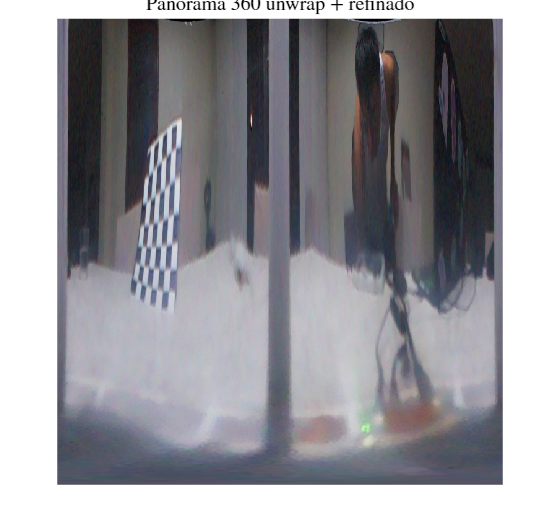

% Pasar la imagen corregida al dominio (r,θ)
% Lee una de las correcciones (por ejemplo la primera)
Iund0 = imread(fullfile(dstFolder, files(5).name));

% Calcula el centro y radio aproximado de la máscara circular
[Hc, Wc, ~] = size(Iund0);
cx = Wc/2;         % centro X en la imagen recortada
cy = Hc/2;         % centro Y
rad = min(cx,cy);  % radio en píxeles

% Parámetros del panorama final
nTheta = 720;           % pasos angulares (ancho de la imagen unwrap)
nR     = round(rad);    % pasos radiales (alto de la imagen unwrap)

% Genera la grilla (θ, r)
theta = linspace(0, 2*pi, nTheta);
rLin  = linspace(0, rad, nR);
[TH, R] = meshgrid(theta, rLin);

% Mapea polares → cartesianas
X = cx + R .* cos(TH);
Y = cy + R .* sin(TH);

% Interpola cada canal y construye el panorama
panorama = zeros(nR, nTheta, size(Iund0,3), 'uint8');
for c = 1:size(Iund0,3)
    chan = double(Iund0(:,:,c));           % pasa a double para interp2
    tmp  = interp2(chan, X, Y, 'cubic', 0);
    panorama(:,:,c) = uint8(tmp);          % de regreso a uint8
end
% Recorte de cualquier borde negro residual
maskP = rgb2gray(panorama) > 5;
bbP   = ceil(regionprops(maskP,'BoundingBox').BoundingBox);
panorama = imcrop(panorama, bbP);

% Suavizado opcional
panorama = imgaussfilt(panorama, 0.5);
panorama = imrotate(panorama,180); % rotar imagen 180°
% Mostrar resultado
figure(); 
imshow(panorama);
title('Panorama 360 ejemplo','Interpreter','latex');

% =========================================================================
% Paso 2) Reconstruir imágenes sin distorsión para generar panoramas
% =========================================================================

%% 2.1) Define carpetas origen y destino
srcFolder = 'img_sindistor';    % Imágenes ya undistort + recortadas
dstFolder = 'img_panorama';     % Aquí guardaremos los panoramas
if ~exist(dstFolder,'dir')
    mkdir(dstFolder);
end

%% 2.2) Lista todas las imágenes corregidas
files = dir(fullfile(srcFolder,'*.png'));

%% 2.3) Parámetros constantes del unwrap
nTheta = 720;  % Pasos angulares (ancho)
% nR lo calculamos por imagen

for k = 1:numel(files)
    %% 2.4) Leer la imagen undistorted
    fname = files(k).name;
    Iund0 = imread(fullfile(srcFolder,fname));
    
    %% 2.5) Calcular centro y radio a partir de su tamaño
    [Hc, Wc, ~] = size(Iund0);
    cx = Wc/2;         % centro X
    cy = Hc/2;         % centro Y
    rad = min(cx,cy);  % radio en píxeles
    
    %% 2.6) Grilla polar → cartesiano para esta imagen
    nR    = round(rad);               % pasos radiales (alto)
    theta = linspace(0,2*pi,nTheta);  
    rLin  = linspace(0,rad,nR);       
    [TH,R] = meshgrid(theta,rLin);    
    X     = cx + R .* cos(TH);        
    Y     = cy + R .* sin(TH);        
    
    %% 2.7) Interpolar cada canal usando 'cubic' y relleno 0
    Iund_d = im2double(Iund0);                
    panorama = zeros(nR, nTheta, size(Iund0,3)); 
    for c = 1:size(Iund0,3)
        chan = Iund_d(:,:,c);
        tmp  = interp2(chan, X, Y, 'cubic', 0);
        panorama(:,:,c) = tmp;
    end
    
    %% 2.8) Recorte automático de bordes negros residuales
    maskP = rgb2gray(panorama) > 5/255;  
    bbP   = ceil(regionprops(maskP,'BoundingBox').BoundingBox);
    panoC = imcrop(panorama, bbP);
    
    %% 2.9) Suavizado opcional y rotación 180°
    panoC = imgaussfilt(panoC,0.5);
    panoC = imrotate(panoC,180);
    
    %% 2.10) Convertir de double [0,1] a uint8 y guardar
    pano8 = im2uint8(panoC);
    outName = fullfile(dstFolder, fname(1:end-4) + "_panorama.png");
    imwrite(pano8, outName);
    fprintf("Panorama guardado: %s\n", outName);
end

Panorama guardado: img_panorama\cal0_seg_panorama.png
Panorama guardado: img_panorama\cal10_seg_panorama.png
Panorama guardado: img_panorama\cal11_seg_panorama.png
Panorama guardado: img_panorama\cal12_seg_panorama.png
Panorama guardado: img_panorama\cal13_seg_panorama.png
Panorama guardado: img_panorama\cal14_seg_panorama.png
Panorama guardado: img_panorama\cal15_seg_panorama.png
Panorama guardado: img_panorama\cal16_seg_panorama.png
Panorama guardado: img_panorama\cal17_seg_panorama.png
Panorama guardado: img_panorama\cal18_seg_panorama.png
Panorama guardado: img_panorama\cal19_seg_panorama.png
Panorama guardado: img_panorama\cal1_seg_panorama.png
Panorama guardado: img_panorama\cal2_seg_panorama.png
Panorama guardado: img_panorama\cal3_seg_panorama.png
Panorama guardado: img_panorama\cal4_seg_panorama.png
Panorama guardado: img_panorama\cal5_seg_panorama.png
Panorama guardado: img_panorama\cal6_seg_panorama.png
Panorama guardado: img_panorama\cal7_seg_panorama.png
Panorama guardado:


fprintf(">> Paso 2 completado: panoramas en %s\n", dstFolder);

>> Paso 2 completado: panoramas en img_panorama
